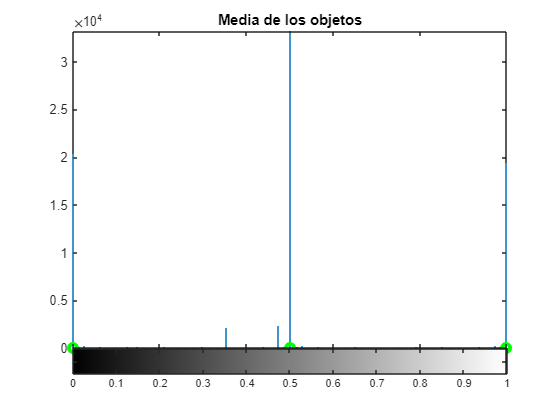

% Cargamos la imagen
filename = './imagenes/circlesBrightDark.png';
n_objetos = 3;

I = convertir_imagen(filename);

[media_obj, sd_obj] = calcular_centroides(I, n_objetos);

mostrar_centroides(I, n_objetos, media_obj);

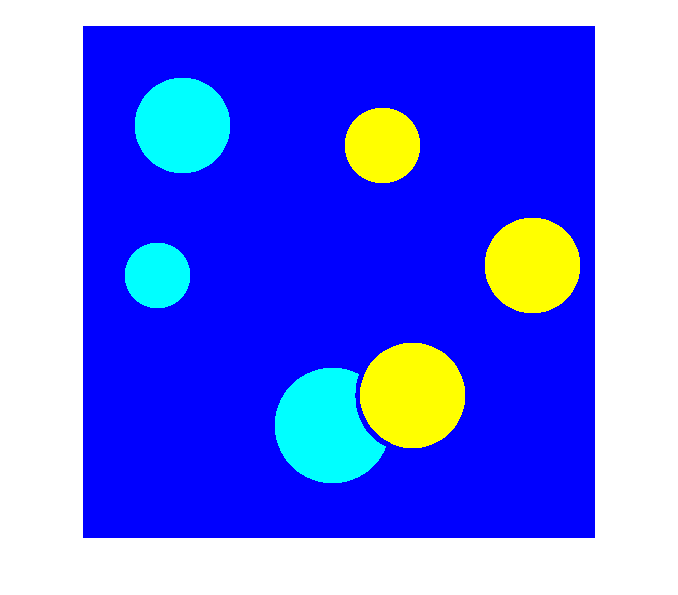

rgb = segmentar(I, n_objetos, media_obj, sd_obj);

figure, imshow(rgb);

function [I] = convertir_imagen(filename)
    info = imfinfo(filename);
    
    if strcmp(info.ColorType,'indexed')
        [Y,map] = imread(filename);
        Z = ind2gray(Y,map);
        I=im2double(Z);
    elseif strcmp(info.ColorType,'truecolor')
        rgb=imread(filename);
        Z=rgb2gray(rgb);
        I=im2double(Z);
    elseif  strcmp(info.ColorType,'grayscale')
        I=im2double(imread(filename)); 
    else
        I=imread(filename);
    end
end

function [media_obj, sd_obj] = calcular_centroides(I, n_objetos)
    pixeles = cell(1, n_objetos);
    % Para cada objeto
    for i = 1:n_objetos
        % Seleccionamos los pixeles del objeto
        fig = figure;
        imshow(I);
        title(sprintf('Selecciona pixeles del objeto %d.', i));
        hold on;
        pixeles{i} = impixel(I);
        close(fig);
    end

    media_obj = zeros(1, n_objetos);
    sd_obj = zeros(1, n_objetos);
    % Para cada objeto
    for i = 1:n_objetos
        % Calculamos la media
        media_obj(i) = mean(pixeles{i}(:,1));
    
        % Calculamos la desviacion
        ds = std(pixeles{i}(:,1)); 
        if (ds == 0) 
            ds = 0.0000001;  
        end
        sd_obj(i) = ds;
    end
end

function mostrar_centroides(I, n_objetos, media_obj)
    % Visualizamos los centroides  
    figure,
    imhist(I);
    hold on,
    for i = 1:n_objetos
        plot(media_obj(i), 0,'go','LineWidth',3); 
    end
    title('Media de los objetos');
    hold off; 
end

function [rgb] = segmentar(I, n_objetos, media_obj, sd_obj)
    [maxX,maxY] = size(I);
    S = zeros(maxX,maxY);
    
    for i = 1:1:maxX 	%Para todas las filas de la imagen
        for j = 1:1:maxY 	%Para todas las columnas de la imagen
            x = I(i,j); %Se toma cada pixel "x" de la imagen
            bayes = zeros(1, n_objetos);
            
            for k = 1:n_objetos
                % se calcula el valor en la función densidad de probabilidad para
                % el valor "x" para cada clase.
                bayes(k) = (1/(sqrt(2*pi)*sd_obj(k))) * exp(-0.5*(x-media_obj(k))'*sd_obj(k)^(-2).*(x-media_obj(k)));  
            end
            
            [~, idx] = max(bayes);
            S(i,j) = idx;
        end
    end
    
    % Pintamos los objetos etiquetados
    rgb = label2rgb(S, 'jet', [.5 .5 .5]);
end